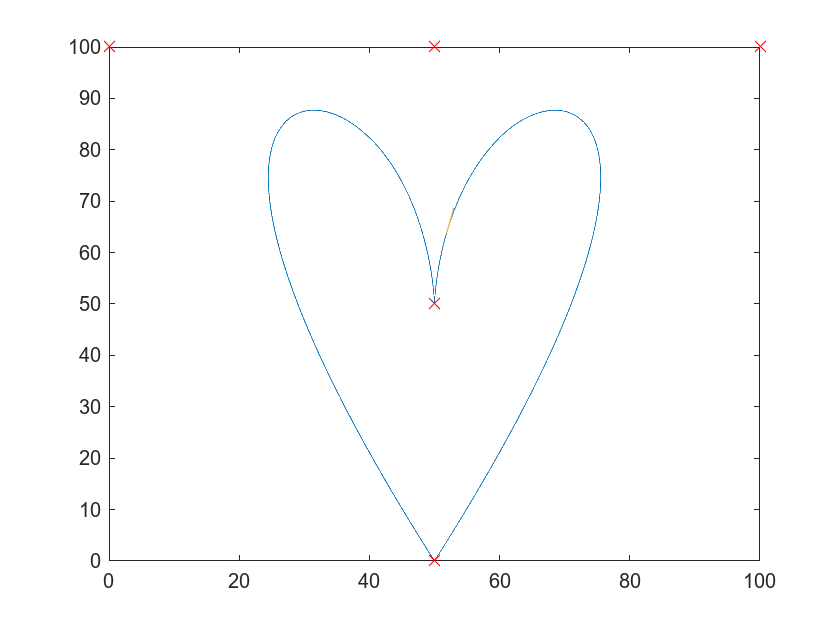

sz = size(PosMAT);
len = sz(1,1);
counter = 0;
tick = 0;
div = 10;
subdiv = floor(len/1000);
Vsumsx = [];
Vsumsy = [];
Vholdx = 0;
Vholdy = 0;
for i = 1:1:len
    Vholdx = Vholdx + VelMAT(i,1);
    Vholdy = Vholdy + VelMAT(i,2);
    counter = counter + 1;
    if counter == subdiv
        tick = tick + 1;
        Vsumsx(tick) = Vholdx/subdiv;
        Vsumsy(tick) = Vholdy/subdiv;
        Vholdx = 0;
        Vholdy = 0;
        counter = 0;
    end
end
j;
for i = 5:subdiv:sz
    j = i/subdiv;
    x = PosMAT(i, 1);
    y = PosMAT(i, 2);
    u = Vsumsx(j);
    v = Vsumsy(j);
    plot(PosMAT(:,1), PosMAT(:,2));
    hold on
    scatter(CPx, CPy, 60, 'red', 'X');
    quiver(x, y, u, v)
    hold off
    pause(0.001);
end